**Problema de les matrícules**

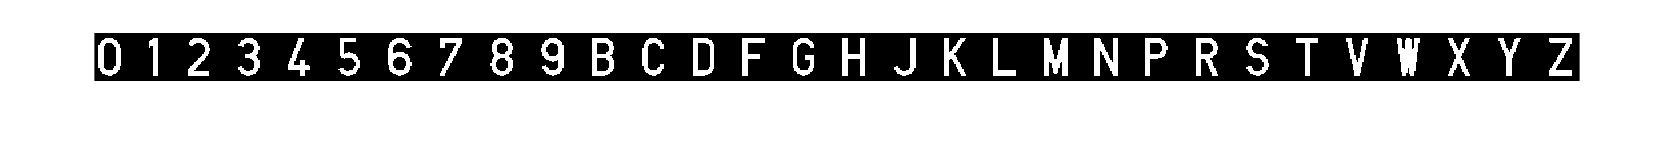

close all;
clear;

I = rgb2gray(imread('Joc_de_caracters.jpg'));
BI = I < 128; % lletres estan en negre
%BI = bwmorph(BI,'majority'); % filtre soroll
%BI = bwmorph(BI,'majority');

imshow(BI);

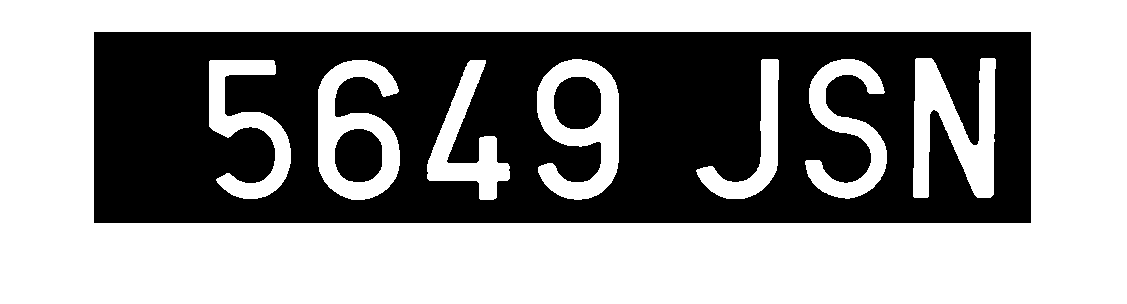


CC = bwconncomp(BI);
%props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
%X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]';

props = regionprops(CC,'Eccentricity','Solidity','Circularity','EulerNumber');
X = [props.Eccentricity;props.Solidity;props.Circularity;props.EulerNumber]';

OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' 'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};
Classifier = TreeBagger(100,X,OUT');

%%%%%%%%%%%%%%%%%%%
% Test
I = rgb2gray(imread('matriucla.jpg'));
BI = I < 80; % separem el background
BI = bwmorph(BI,'majority'); % filtre soroll
BI = bwmorph(BI,'majority');
figure;imshow(BI);

CC = bwconncomp(BI);

%props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
%X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 

props = regionprops(CC,'Eccentricity','Solidity','Circularity','EulerNumber');
X = [props.Eccentricity;props.Solidity;props.Circularity;props.EulerNumber]';

[label,score] = predict(Classifier,X);
%table(Classifier.ClassNames,label,max(score)','VariableNames',{'Name','Label','Score'})
table(Classifier.ClassNames,max(score)','VariableNames',{'Name','Score'})

ans = 30×2 table
    Name     Score
    _____    _____

    {'0'}    0.09 
    {'1'}       0 
    {'2'}    0.18 
    {'3'}    0.14 
    {'4'}     0.1 
    {'5'}    0.11 
    {'6'}    0.08 
    {'7'}    0.41 
    {'8'}    0.02 
    {'9'}    0.13 
    {'B'}    0.01 
    {'C'}    0.13 
    {'D'}    0.09 
    {'F'}    0.03 
    {'G'}    0.34 
    {'H'}    0.04 



matricula = predict(Classifier,X)

matricula = 7×1 cell array
    {'S'}
    {'R'}
    {'7'}
    {'R'}
    {'J'}
    {'S'}
    {'N'}


**Fourier descriptors**

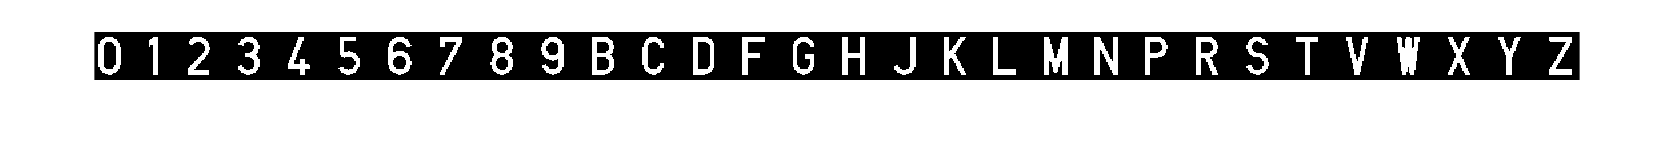

clear;

load Caracteristicas.mat;

X = caracteristicas;

I = imread('Joc_de_caracters.jpg');
I = rgb2gray(I);
h = imhist(I); t = otsuthresh(h);
I = imbinarize(I,t); I = ~I;
imshow(I)

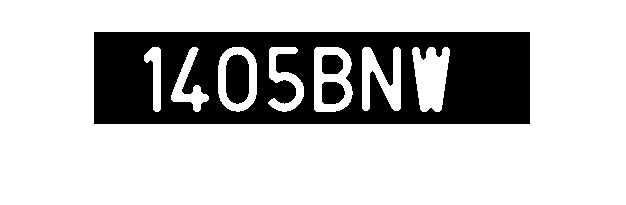


% Separamos la imagen original entre las diferentes componentes connexas (caracterses).
CC = bwconncomp(I);

% Obtenemos imagenes binarias separadas de los caracterses
caracters = regionprops(CC, 'Image');

% Texto para las tablas
OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' 'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};

Md1 = fitcecoc(X,OUT);

% Calculo de los descriptores de Fourier para cada caracters.
FD = [];
for i = 1:30
    FD = [FD, FourierDescriptor(caracters(i).Image)];
end

FD = FD';

eccentricity = regionprops(CC,'Eccentricity');
ECCENTRICITY = cell2mat(struct2cell(eccentricity))';

solidity = regionprops(CC,'Solidity');
SOLIDITY = cell2mat(struct2cell(solidity))';

circularity = regionprops(CC,'Circularity');
CIRCULARITY = cell2mat(struct2cell(circularity))';

eulerNumber = regionprops(CC,'EulerNumber');
holes = cell2mat(struct2cell(eulerNumber));

for i = 1:size(holes,2)
    holes(1,i) = abs(holes(1,i)-1);
end
HOL = holes';

majorAxis = regionprops(CC,'MajoraxisLength');
minorAxis = regionprops(CC,'MinoraxisLength');
perimeter = regionprops(CC,'Perimeter');
MA = cell2mat(struct2cell(majorAxis));
PE = cell2mat(struct2cell(perimeter));
RELATION_MAJOR = MA./PE;
RELATION_MAJOR = RELATION_MAJOR';

mA = cell2mat(struct2cell(minorAxis));
RELATION_MINOR = mA./PE;
RELATION_MINOR = RELATION_MINOR';

X = [RELATION_MAJOR,RELATION_MINOR,ECCENTRICITY,HOL,FD,SOLIDITY,CIRCULARITY];

Classifier = TreeBagger(1000,X,OUT');

%%%%%%%%%%%%%%%%%%%
% Test
I = rgb2gray(imread('matricula4.jpg'));

BI = I < 28; % separem el background
BI = imclose(imopen(BI,strel('disk',2)),strel('disk',2));

figure;imshow(BI);

CC = bwconncomp(BI);

%props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
%X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 

caracters = regionprops(CC, 'Image');
FD = [];
for i = 1:7
    FD = [FD, FourierDescriptor(caracters(i).Image)];
end

FD = FD';

eccentricity = regionprops(CC,'Eccentricity');
ECCENTRICITY = cell2mat(struct2cell(eccentricity))';

solidity = regionprops(CC,'Solidity');
SOLIDITY = cell2mat(struct2cell(solidity))';

circularity = regionprops(CC,'Circularity');
CIRCULARITY = cell2mat(struct2cell(circularity))';

eulerNumber = regionprops(CC,'EulerNumber');
holes = cell2mat(struct2cell(eulerNumber));

for i = 1:size(holes,2)
    holes(1,i) = abs(holes(1,i)-1);
end
HOL = holes';


majorAxis = regionprops(CC,'MajoraxisLength');
minorAxis = regionprops(CC,'MinoraxisLength');
perimeter = regionprops(CC,'Perimeter');
MA = cell2mat(struct2cell(majorAxis));
PE = cell2mat(struct2cell(perimeter));
RELATION_MAJOR = MA./PE;
RELATION_MAJOR = RELATION_MAJOR';

mA = cell2mat(struct2cell(minorAxis));
RELATION_MINOR = mA./PE;
RELATION_MINOR = RELATION_MINOR';

X = [RELATION_MAJOR,RELATION_MINOR,ECCENTRICITY,HOL,FD,SOLIDITY,CIRCULARITY];

[label,score] = predict(Classifier,X);
%table(Classifier.ClassNames,label,max(score)','VariableNames',{'Name','Label','Score'})
table(Classifier.ClassNames,max(score)','VariableNames',{'Name','Score'})

ans = 30×2 table
    Name     Score
    _____    _____

    {'0'}     0.25
    {'1'}    0.384
    {'2'}    0.024
    {'3'}    0.044
    {'4'}    0.239
    {'5'}    0.332
    {'6'}    0.059
    {'7'}    0.181
    {'8'}     0.11
    {'9'}    0.126
    {'B'}    0.325
    {'C'}     0.09
    {'D'}    0.169
    {'F'}    0.078
    {'G'}    0.073
    {'H'}    0.142



matricula = predict(Classifier,X)

matricula = 7×1 cell array
    {'1'}
    {'4'}
    {'0'}
    {'5'}
    {'B'}
    {'N'}
    {'W'}


**Other tests**

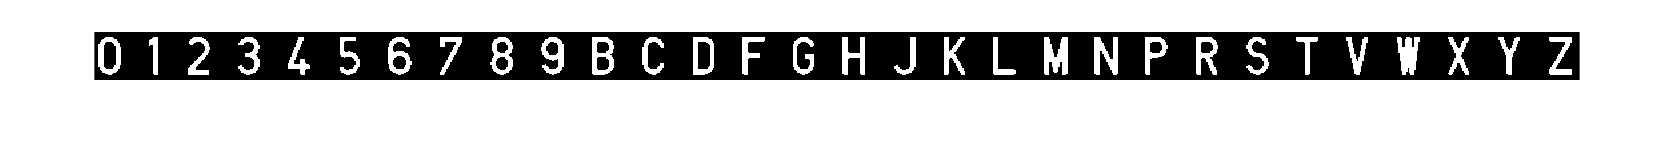

clear;


I = rgb2gray(imread('Joc_de_caracters.jpg'));
BI = I < 128;
BI = bwmorph(BI,'majority'); % filtre soroll
BI = bwmorph(BI,'majority');
imshow(BI)

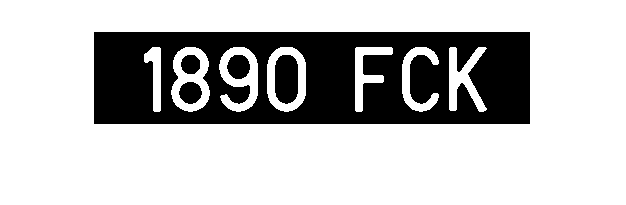


CC = bwconncomp(BI);
% Obtenim els 30 caràcters del joc binaritzat 
caracters = regionprops(CC, 'Image');


% Calculo de los descriptores de Fourier para cada caracters.
FD = [];
m = 3; n = 3;
for i = 1:CC.NumObjects % for i = 1:30
    caracter_i = centerobject(caracters(i).Image);
    FD = [FD, gfd(caracter_i,m,n)];                                          %#ok<AGROW> 
end
FD = FD';

eccentricity = regionprops(CC,'Eccentricity');
ECCENTRICITY = cell2mat(struct2cell(eccentricity))';

solidity = regionprops(CC,'Solidity');
SOLIDITY = cell2mat(struct2cell(solidity))';

circularity = regionprops(CC,'Circularity');
CIRCULARITY = cell2mat(struct2cell(circularity))';

eulerNumber = regionprops(CC,'EulerNumber');
HOLES = cell2mat(struct2cell(eulerNumber))';

%for i = 1:size(holes,2)
%    holes(1,i) = abs(holes(1,i)-1);
%end

majorAxis = regionprops(CC,'MajoraxisLength');
minorAxis = regionprops(CC,'MinoraxisLength');
perimeter = regionprops(CC,'Perimeter');
MA = cell2mat(struct2cell(majorAxis));
mA = cell2mat(struct2cell(minorAxis));
PERIMETER = cell2mat(struct2cell(perimeter));

RELATION_MAJOR = (MA./PERIMETER)';
RELATION_MINOR = (mA./PERIMETER)';

X = [ECCENTRICITY,HOLES,SOLIDITY,CIRCULARITY,RELATION_MAJOR,RELATION_MINOR,FD];
OUT = {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9' 'B' 'C' 'D' 'F' 'G' 'H' 'J' ...
    'K' 'L' 'M' 'N' 'P' 'R' 'S' 'T' 'V' 'W' 'X' 'Y' 'Z'};
Classifier = TreeBagger(100,X,OUT');


%fd_names = {'FD_0', 'FD_1', 'FD_2', 'FD_3', 'FD_4', 'FD_5', 'FD_6', ...
%    'FD_7', 'FD_8', 'FD_9', 'FD_B', 'FD_C', 'FD_D', 'FD_F', 'FD_G', ...
%    'FD_H', 'FD_J', 'FD_K', 'FD_L', 'FD_M', 'FD_N', 'FD_P', 'FD_R', ...
%    'FD_S','FD_T', 'FD_V', 'FD_W', 'FD_X', 'FD_Y', 'FD_Z'};


%%%%%%%%%%%%%%%%%%%
% Test
I = rgb2gray(imread('matricula5.jpg'));
%I = imread('W_molt_deformat.jpg');
    
BI = I < 35; % separem el background
%BI = I > 200; % separem el background
BI = bwmorph(BI,'majority'); % filtre soroll
BI = bwmorph(BI,'majority');

figure;imshow(BI);

CC = bwconncomp(BI);

%props = regionprops(CC,'Area','MajorAxisLength','MinorAxisLength');
%X = [props.Area; props.MajorAxisLength; props.MinorAxisLength;]'; 

caracters = regionprops(CC, 'Image');
FD = [];
for i = 1:CC.NumObjects
    FD = [FD, FourierDescriptor(caracters(i).Image)];
end

FD = FD';

eccentricity = regionprops(CC,'Eccentricity');
ECCENTRICITY = cell2mat(struct2cell(eccentricity))';

solidity = regionprops(CC,'Solidity');
SOLIDITY = cell2mat(struct2cell(solidity))';

circularity = regionprops(CC,'Circularity');
CIRCULARITY = cell2mat(struct2cell(circularity))';

eulerNumber = regionprops(CC,'EulerNumber');
HOLES = cell2mat(struct2cell(eulerNumber))';

%for i = 1:size(holes,2)
%    holes(1,i) = abs(holes(1,i)-1);
%end


majorAxis = regionprops(CC,'MajoraxisLength');
minorAxis = regionprops(CC,'MinoraxisLength');
perimeter = regionprops(CC,'Perimeter');
MA = cell2mat(struct2cell(majorAxis));
PE = cell2mat(struct2cell(perimeter));
RELATION_MAJOR = MA./PE;
RELATION_MAJOR = RELATION_MAJOR';

mA = cell2mat(struct2cell(minorAxis));
RELATION_MINOR = mA./PE;
RELATION_MINOR = RELATION_MINOR';

X = [ECCENTRICITY,HOLES,SOLIDITY,CIRCULARITY,RELATION_MAJOR,RELATION_MINOR,FD];

[label,score] = predict(Classifier,X);
table(Classifier.ClassNames,score','VariableNames',{'Name','Score'})

ans = 30×2 table
    Name        Score    
    _____    ____________

    {'0'}    [1×7 double]
    {'1'}    [1×7 double]
    {'2'}    [1×7 double]
    {'3'}    [1×7 double]
    {'4'}    [1×7 double]
    {'5'}    [1×7 double]
    {'6'}    [1×7 double]
    {'7'}    [1×7 double]
    {'8'}    [1×7 double]
    {'9'}    [1×7 double]
    {'B'}    [1×7 double]
    {'C'}    [1×7 double]
    {'D'}    [1×7 double]
    {'F'}    [1×7 double]
    {'G'}    [1×7 double]
    {'H'}    [1×7 double]



ans = sortrows(ans,'Score','descend')

ans = 30×2 table
    Name        Score    
    _____    ____________

    {'1'}    [1×7 double]
    {'T'}    [1×7 double]
    {'K'}    [1×7 double]
    {'M'}    [1×7 double]
    {'Y'}    [1×7 double]
    {'7'}    [1×7 double]
    {'W'}    [1×7 double]
    {'B'}    [1×7 double]
    {'D'}    [1×7 double]
    {'J'}    [1×7 double]
    {'9'}    [1×7 double]
    {'2'}    [1×7 double]
    {'V'}    [1×7 double]
    {'5'}    [1×7 double]
    {'X'}    [1×7 double]
    {'6'}    [1×7 double]


resultat = (predict(Classifier,X));
resultat

resultat = 7×1 cell array
    {'1'}
    {'8'}
    {'9'}
    {'0'}
    {'F'}
    {'C'}
    {'K'}



%fprintf(matricula)